# Generating the impact map for the three-link 2D biped (Assignment 2, continued)

Once the biped completes a step, the swing foot hits the ground and afterwards the swing leg becomes the **new** stance leg and the stance leg becomes the **new** swing leg.  The **impact map,** which this scripts generates, defines such a transition. Indeed, the impact map, maps the state of the robot right before the impact to its state right after the impact. Mathematically, **assuming the impact and switching of the legs roles is instantenous**, we have 


$$\Delta(q^-, \dot q^-) = (q^+, \dot q^+)$$


where $(q^-, \dot q^-)$ is the state of the robot right before the impact and $(q^+, \dot q^+)$ denotes its state right after the impact. This script generates the impact map $\Delta$. 

**Note**: In this script we use the notation [q1_m, q2_m, q3_m] for $q^-$ and [q1_p, q2_p, q3_p] for $q^+$. Similarly, we use [dq1_m, dq2_m, dq3_m] for $\dot q^-$ and [dq1_p, dq2_p, dq3_p] for $\dot q^+$.

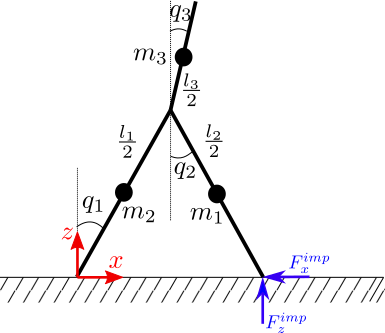

## Angles:

We can write the impact map as:


$$\Delta(q^-, \dot q^-) = (\Delta_q(q^-), \Delta_{\dot q} (q^-, \dot q^-))$$


This is true, because before and after impact the configuration of the robot (not the velocites) remains the same. So, for $\Delta_q$ all you need is to **swap** the indices of the stance and swing legs appropriately, taking into account that we always use index 1 for the stance leg and index 2 for the swing leg. You will be doing this directly in the impact.m function. 

syms q1_m q2_m q3_m q1_p q2_p q3_p

## Angular Velocities:

Unlike angles, which only needed bookeeping, calculation of angular velocities (i.e., $\dot q^+$) needs some physics. We will follow the approach of [McGeer 1988](https://aerovel.com/wp-content/uploads/2015/03/Stability-and-control-of-two-dimensional-bipedal-walking.pdf), i.e. method of **conservation of angular momentum** to calculate the angular velocities after impact. 

In the following cells you need the symbolic outputs of generate_kinematics. So, we first run generate_kinematics:

**Note: Before running generate_kinematics,** **update it to include velocities of (x_h, z_h) and (x_swf, z_swf) that is (dx_h, dz_h) and (dx_swf, dz_swf). Later we will be using them.** 

generate_kinematics
generate_dynamics

$$T1 = \frac{m_{1}\,\left(\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,{\cos\left(q_{1}\right)}^{2}}{4}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}}{4}\right)}{2}$$

$$T2 = \frac{m_{2}\,\left({\left({\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)-\frac{{\mathrm{dq}}_{2}\,l_{2}\,\cos\left(q_{2}\right)}{2}\right)}^{2}+{\left({\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)-\frac{{\mathrm{dq}}_{2}\,l_{2}\,\sin\left(q_{2}\right)}{2}\right)}^{2}\right)}{2}$$

$$T3 = \frac{m_{3}\,\left({\left({\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)+\frac{{\mathrm{dq}}_{3}\,l_{3}\,\cos\left(q_{3}\right)}{2}\right)}^{2}+{\left({\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)+\frac{{\mathrm{dq}}_{3}\,l_{3}\,\sin\left(q_{3}\right)}{2}\right)}^{2}\right)}{2}$$

$$T = \frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{1}}{8}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{3}}{2}+\frac{{{\mathrm{dq}}_{2}}^{2}\,{l_{2}}^{2}\,m_{2}}{8}+\frac{{{\mathrm{dq}}_{3}}^{2}\,{l_{3}}^{2}\,m_{3}}{8}-\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)}{2}+\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)}{2}$$

$$V = g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\right)-\frac{l_{2}\,\cos\left(q_{2}\right)}{2}\right)+g\,m_{3}\,\left(l_{1}\,\cos\left(q_{1}\right)+\frac{l_{3}\,\cos\left(q_{3}\right)}{2}\right)+\frac{g\,l_{1}\,m_{1}\,\cos\left(q_{1}\right)}{2}$$

$$L = \frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{1}}{8}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{3}}{2}+\frac{{{\mathrm{dq}}_{2}}^{2}\,{l_{2}}^{2}\,m_{2}}{8}+\frac{{{\mathrm{dq}}_{3}}^{2}\,{l_{3}}^{2}\,m_{3}}{8}-g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\right)-\frac{l_{2}\,\cos\left(q_{2}\right)}{2}\right)-g\,m_{3}\,\left(l_{1}\,\cos\left(q_{1}\right)+\frac{l_{3}\,\cos\left(q_{3}\right)}{2}\right)-\frac{g\,l_{1}\,m_{1}\,\cos\left(q_{1}\right)}{2}-\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)}{2}+\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)}{2}$$

$$dLddq1 = \frac{{\mathrm{dq}}_{1}\,{l_{1}}^{2}\,m_{1}}{4}+{\mathrm{dq}}_{1}\,{l_{1}}^{2}\,m_{2}+{\mathrm{dq}}_{1}\,{l_{1}}^{2}\,m_{3}-\frac{{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)}{2}+\frac{{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)}{2}$$

$$dLddq2 = \frac{l_{2}\,m_{2}\,\left({\mathrm{dq}}_{2}\,l_{2}-2\,{\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}-q_{2}\right)\right)}{4}$$

$$dLddq3 = \frac{l_{3}\,m_{3}\,\left({\mathrm{dq}}_{3}\,l_{3}+2\,{\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}-q_{3}\right)\right)}{4}$$

$$dLddq1\_dt = {\mathrm{dq}}_{1}\,\left(\frac{{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2}-\frac{{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2}\right)+{\mathrm{ddq}}_{1}\,\left(\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}\right)-\frac{{\mathrm{ddq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)}{2}+\frac{{\mathrm{ddq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)}{2}-\frac{{{\mathrm{dq}}_{2}}^{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2}+\frac{{{\mathrm{dq}}_{3}}^{2}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2}$$

$$dLddq2\_dt = \frac{l_{2}\,m_{2}\,\left(2\,l_{1}\,\sin\left(q_{1}-q_{2}\right)\,{{\mathrm{dq}}_{1}}^{2}-2\,{\mathrm{dq}}_{2}\,l_{1}\,\sin\left(q_{1}-q_{2}\right)\,{\mathrm{dq}}_{1}+{\mathrm{ddq}}_{2}\,l_{2}-2\,{\mathrm{ddq}}_{1}\,l_{1}\,\cos\left(q_{1}-q_{2}\right)\right)}{4}$$

$$dLddq3\_dt = \frac{l_{3}\,m_{3}\,\left(-2\,l_{1}\,\sin\left(q_{1}-q_{3}\right)\,{{\mathrm{dq}}_{1}}^{2}+2\,{\mathrm{dq}}_{3}\,l_{1}\,\sin\left(q_{1}-q_{3}\right)\,{\mathrm{dq}}_{1}+{\mathrm{ddq}}_{3}\,l_{3}+2\,{\mathrm{ddq}}_{1}\,l_{1}\,\cos\left(q_{1}-q_{3}\right)\right)}{4}$$

$$Eq1 = {\mathrm{dq}}_{1}\,\left(\frac{{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2}-\frac{{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2}\right)+{\mathrm{ddq}}_{1}\,\left(\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}\right)-\frac{g\,l_{1}\,m_{1}\,\sin\left(q_{1}\right)}{2}-g\,l_{1}\,m_{2}\,\sin\left(q_{1}\right)-g\,l_{1}\,m_{3}\,\sin\left(q_{1}\right)-\frac{{\mathrm{ddq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)}{2}+\frac{{\mathrm{ddq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)}{2}-\frac{{{\mathrm{dq}}_{2}}^{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2}+\frac{{{\mathrm{dq}}_{3}}^{2}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2}-\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2}+\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2}$$

$$Eq2 = \frac{l_{2}\,m_{2}\,\left(2\,l_{1}\,\sin\left(q_{1}-q_{2}\right)\,{{\mathrm{dq}}_{1}}^{2}-2\,{\mathrm{dq}}_{2}\,l_{1}\,\sin\left(q_{1}-q_{2}\right)\,{\mathrm{dq}}_{1}+{\mathrm{ddq}}_{2}\,l_{2}-2\,{\mathrm{ddq}}_{1}\,l_{1}\,\cos\left(q_{1}-q_{2}\right)\right)}{4}+\frac{g\,l_{2}\,m_{2}\,\sin\left(q_{2}\right)}{2}+\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2}$$

$$Eq3 = \frac{l_{3}\,m_{3}\,\left(-2\,l_{1}\,\sin\left(q_{1}-q_{3}\right)\,{{\mathrm{dq}}_{1}}^{2}+2\,{\mathrm{dq}}_{3}\,l_{1}\,\sin\left(q_{1}-q_{3}\right)\,{\mathrm{dq}}_{1}+{\mathrm{ddq}}_{3}\,l_{3}+2\,{\mathrm{ddq}}_{1}\,l_{1}\,\cos\left(q_{1}-q_{3}\right)\right)}{4}-\frac{g\,l_{3}\,m_{3}\,\sin\left(q_{3}\right)}{2}-\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2}$$

$$G = \left(\begin{array}{c} -\frac{g\,l_{1}\,\sin\left(q_{1}\right)\,\left(m_{1}+2\,m_{2}+2\,m_{3}\right)}{2}\\ \frac{g\,l_{2}\,m_{2}\,\sin\left(q_{2}\right)}{2}\\ -\frac{g\,l_{3}\,m_{3}\,\sin\left(q_{3}\right)}{2} \end{array}\right)$$

$$M = \begin{array}{l} \left(\begin{array}{ccc} \frac{{l_{1}}^{2}\,\left(m_{1}+4\,m_{2}+4\,m_{3}\right)}{4} & \sigma_{1} & \sigma_{2}\\ \sigma_{1} & \frac{{l_{2}}^{2}\,m_{2}}{4} & 0\\ \sigma_{2} & 0 & \frac{{l_{3}}^{2}\,m_{3}}{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)}{2}\\ \sigma_{2}=\frac{l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)}{2} \end{array}$$

$$C = \left(\begin{array}{ccc} 0 & -\frac{{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2} & \frac{{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2}\\ \frac{{\mathrm{dq}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2} & 0 & 0\\ -\frac{{\mathrm{dq}}_{1}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2} & 0 & 0 \end{array}\right)$$

$$error = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$del\_W = u_{1}\,{\mathrm{delq}}_{1}+u_{2}\,{\mathrm{delq}}_{2}+\left(-u_{1}-u_{2}\right)\,{\mathrm{delq}}_{3}$$

$$B = \left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ -1 & -1 \end{array}\right)$$

For the calculation of angular momentum before and after impact you first need to calculate the positions and velocites of the masses $m_1$, $m_2$ and $m_3$ as well as the hip joint before and after impact.

**Positions and velocities of the masses and the hip joint before the impact:**

syms dq1_m dq2_m dq3_m dq1_p dq2_p dq3_p
x1_m = l1/2*sin(q1_m); 
z1_m = l1/2*cos(q1_m);
x2_m = l1*sin(q1_m) - l2/2*sin(q2_m);
z2_m = l1*cos(q1_m) - l2/2*cos(q2_m);
x3_m = l1*sin(q1_m) + l3/2*sin(q3_m);
z3_m = l1*cos(q1_m) + l3/2*cos(q3_m);
xh_m = l1*sin(q1_m);
zh_m = l1*cos(q1_m);
xswf_m = - l2*sin(q2_m) + l1*sin(q1_m);
zswf_m = - l2*cos(q2_m) + l1*cos(q1_m);
% 
dx1_m = diff(x1_m, q1_m) * dq1_m + diff(x1_m, q2_m) * dq2_m;
dz1_m = diff(z1_m, q1_m) * dq1_m + diff(z1_m, q2_m) * dq2_m;
dx2_m = diff(x2_m, q1_m) * dq1_m + diff(x2_m, q2_m) * dq2_m;
dz2_m = diff(z2_m, q1_m) * dq1_m + diff(z2_m, q2_m) * dq2_m;
dx3_m = diff(x3_m, q1_m) * dq1_m + diff(x3_m, q3_m) * dq3_m;
dz3_m = diff(z3_m, q1_m) * dq1_m + diff(z3_m, q3_m) * dq3_m;
dxh_m = diff(xh_m, q1_m) * dq1_m;
dzh_m = diff(zh_m, q1_m) * dq1_m;
dxswf_m = diff(xswf_m, q1_m) * dq1_m + diff(xswf_m, q2_m) * dq2_m;
dzswf_m = diff(zswf_m, q1_m) * dq1_m + diff(zswf_m, q2_m) * dq2_m;

**Positions and velocities of the masses and the hip joint after the impact:**

syms dq1_p dq2_p dq3_p dq1_p dq2_p dq3_p
x1_p = l1/2*sin(q1_p);
z1_p = l1/2*cos(q1_p);
x2_p = l1*sin(q1_p) - l2/2*sin(q2_p); 
z2_p = l1*cos(q1_p) - l2/2*cos(q2_p);
x3_p = l1*sin(q1_p) + l3/2*sin(q3_p);
z3_p = l1*cos(q1_p) + l3/2*cos(q3_p);
xh_p = l1*sin(q1_p);
zh_p = l1*cos(q1_p);
xswf_p = l1*sin(q1_p) - l2*sin(q2_p);
zswf_p = l1*cos(q1_p) - l2*cos(q2_p);
% 
dx1_p = diff(x1_p, q1_p) * dq1_p;
dz1_p = diff(z1_p, q1_p) * dq1_p;
dx2_p = diff(x2_p, q1_p) * dq1_p + diff(x2_p, q2_p) * dq2_p;
dz2_p = diff(z2_p, q1_p) * dq1_p + diff(z2_p, q2_p) * dq2_p;
dx3_p = diff(x3_p, q1_p) * dq1_p + diff(x3_p, q3_p) * dq3_p;
dz3_p = diff(z3_p, q1_p) * dq1_p + diff(z3_p, q3_p) * dq3_p;
dxh_p = diff(xh_p, q1_p) * dq1_p;
dzh_p = diff(zh_p, q1_p) * dq1_p;
dxswf_p = diff(xswf_p, q1_p) * dq1_p + diff(xswf_p, q2_p) * dq2_p;
dzswf_p = diff(zswf_p, q1_p) * dq1_p + diff(zswf_p, q2_p) * dq2_p;

Positions and velocites before and after impact in vector form:

r1_m = [x1_m, z1_m]

$$r1\_m = \left(\begin{array}{cc} \frac{l_{1}\,\sin\left(q_{1,m}\right)}{2} & \frac{l_{1}\,\cos\left(q_{1,m}\right)}{2} \end{array}\right)$$

r2_m = [x2_m, z2_m]

$$r2\_m = \left(\begin{array}{cc} l_{1}\,\sin\left(q_{1,m}\right)-\frac{l_{2}\,\sin\left(q_{2,m}\right)}{2} & l_{1}\,\cos\left(q_{1,m}\right)-\frac{l_{2}\,\cos\left(q_{2,m}\right)}{2} \end{array}\right)$$

r3_m = [x3_m, z3_m]

$$r3\_m = \left(\begin{array}{cc} l_{1}\,\sin\left(q_{1,m}\right)+\frac{l_{3}\,\sin\left(q_{3,m}\right)}{2} & l_{1}\,\cos\left(q_{1,m}\right)+\frac{l_{3}\,\cos\left(q_{3,m}\right)}{2} \end{array}\right)$$

rh_m = [xh_m, zh_m]

$$rh\_m = \left(\begin{array}{cc} l_{1}\,\sin\left(q_{1,m}\right) & l_{1}\,\cos\left(q_{1,m}\right) \end{array}\right)$$

rswf_m = [xswf_m, zswf_m]

$$rswf\_m = \left(\begin{array}{cc} l_{1}\,\sin\left(q_{1,m}\right)-l_{2}\,\sin\left(q_{2,m}\right) & l_{1}\,\cos\left(q_{1,m}\right)-l_{2}\,\cos\left(q_{2,m}\right) \end{array}\right)$$

r1_p = [x1_p, z1_p]

$$r1\_p = \left(\begin{array}{cc} \frac{l_{1}\,\sin\left(q_{1,p}\right)}{2} & \frac{l_{1}\,\cos\left(q_{1,p}\right)}{2} \end{array}\right)$$

r2_p = [x2_p, z2_p]

$$r2\_p = \left(\begin{array}{cc} l_{1}\,\sin\left(q_{1,p}\right)-\frac{l_{2}\,\sin\left(q_{2,p}\right)}{2} & l_{1}\,\cos\left(q_{1,p}\right)-\frac{l_{2}\,\cos\left(q_{2,p}\right)}{2} \end{array}\right)$$

r3_p = [x3_p, z3_p]

$$r3\_p = \left(\begin{array}{cc} l_{1}\,\sin\left(q_{1,p}\right)+\frac{l_{3}\,\sin\left(q_{3,p}\right)}{2} & l_{1}\,\cos\left(q_{1,p}\right)+\frac{l_{3}\,\cos\left(q_{3,p}\right)}{2} \end{array}\right)$$

rh_p = [xh_p, zh_p]

$$rh\_p = \left(\begin{array}{cc} l_{1}\,\sin\left(q_{1,p}\right) & l_{1}\,\cos\left(q_{1,p}\right) \end{array}\right)$$

rswf_p = [xswf_p, zswf_p]

$$rswf\_p = \left(\begin{array}{cc} l_{1}\,\sin\left(q_{1,p}\right)-l_{2}\,\sin\left(q_{2,p}\right) & l_{1}\,\cos\left(q_{1,p}\right)-l_{2}\,\cos\left(q_{2,p}\right) \end{array}\right)$$

%dr1_m = diff(r1_m, q1_m) * dq1_m + diff(r1_m, q2_m) * dq2_m + diff(r1_m, q3_m) * dq3_m
%dr2_m = diff(r2_m, q1_m) * dq1_m + diff(r2_m, q2_m) * dq2_m + diff(r2_m, q3_m) * dq3_m
%dr3_m = diff(r3_m, q1_m) * dq1_m + diff(r3_m, q2_m) * dq2_m + diff(r3_m, q3_m) * dq3_m
%drh_m = diff(rh_m, q1_m) * dq1_m + diff(rh_m, q2_m) * dq2_m + diff(rh_m, q3_m) * dq3_m
%drswf_m = diff(rswf_m, q1_m) * dq1_m + diff(rswf_m, q2_m) * dq2_m + diff(rswf_m, q3_m) * dq3_m
%dr1_p = diff(r1_p, q1_p) * dq1_p + diff(r1_p, q2_p) * dq2_p + diff(r1_p, q3_p) * dq3_p
%dr2_p = diff(r2_p, q1_p) * dq1_p + diff(r2_p, q2_p) * dq2_p + diff(r2_p, q3_p) * dq3_p
%dr3_p = diff(r3_p, q1_p) * dq1_p + diff(r3_p, q2_p) * dq2_p + diff(r3_p, q3_p) * dq3_p
%drh_p = diff(rh_p, q1_p) * dq1_p + diff(rh_p, q2_p) * dq2_p + diff(rh_p, q3_p) * dq3_p
%drswf_p = diff(rswf_p, q1_p) * dq1_p + diff(rswf_p, q2_p) * dq2_p + diff(rswf_p, q3_p) * dq3_p

dr1_m = [dx1_m, dz1_m]

$$dr1\_m = \left(\begin{array}{cc} \frac{{\mathrm{dq}}_{1,m}\,l_{1}\,\cos\left(q_{1,m}\right)}{2} & -\frac{{\mathrm{dq}}_{1,m}\,l_{1}\,\sin\left(q_{1,m}\right)}{2} \end{array}\right)$$

dr2_m = [dx2_m, dz2_m]

$$dr2\_m = \left(\begin{array}{cc} {\mathrm{dq}}_{1,m}\,l_{1}\,\cos\left(q_{1,m}\right)-\frac{{\mathrm{dq}}_{2,m}\,l_{2}\,\cos\left(q_{2,m}\right)}{2} & \frac{{\mathrm{dq}}_{2,m}\,l_{2}\,\sin\left(q_{2,m}\right)}{2}-{\mathrm{dq}}_{1,m}\,l_{1}\,\sin\left(q_{1,m}\right) \end{array}\right)$$

dr3_m = [dx3_m, dz3_m]

$$dr3\_m = \left(\begin{array}{cc} {\mathrm{dq}}_{1,m}\,l_{1}\,\cos\left(q_{1,m}\right)+\frac{{\mathrm{dq}}_{3,m}\,l_{3}\,\cos\left(q_{3,m}\right)}{2} & -{\mathrm{dq}}_{1,m}\,l_{1}\,\sin\left(q_{1,m}\right)-\frac{{\mathrm{dq}}_{3,m}\,l_{3}\,\sin\left(q_{3,m}\right)}{2} \end{array}\right)$$

drh_m = [dxh_m, dzh_m]

$$drh\_m = \left(\begin{array}{cc} {\mathrm{dq}}_{1,m}\,l_{1}\,\cos\left(q_{1,m}\right) & -{\mathrm{dq}}_{1,m}\,l_{1}\,\sin\left(q_{1,m}\right) \end{array}\right)$$

drswf_m = [dxswf_m, dzswf_m]

$$drswf\_m = \left(\begin{array}{cc} {\mathrm{dq}}_{1,m}\,l_{1}\,\cos\left(q_{1,m}\right)-{\mathrm{dq}}_{2,m}\,l_{2}\,\cos\left(q_{2,m}\right) & {\mathrm{dq}}_{2,m}\,l_{2}\,\sin\left(q_{2,m}\right)-{\mathrm{dq}}_{1,m}\,l_{1}\,\sin\left(q_{1,m}\right) \end{array}\right)$$

dr1_p = [dx1_p, dz1_p]

$$dr1\_p = \left(\begin{array}{cc} \frac{{\mathrm{dq}}_{1,p}\,l_{1}\,\cos\left(q_{1,p}\right)}{2} & -\frac{{\mathrm{dq}}_{1,p}\,l_{1}\,\sin\left(q_{1,p}\right)}{2} \end{array}\right)$$

dr2_p = [dx2_p, dz2_p]

$$dr2\_p = \left(\begin{array}{cc} {\mathrm{dq}}_{1,p}\,l_{1}\,\cos\left(q_{1,p}\right)-\frac{{\mathrm{dq}}_{2,p}\,l_{2}\,\cos\left(q_{2,p}\right)}{2} & \frac{{\mathrm{dq}}_{2,p}\,l_{2}\,\sin\left(q_{2,p}\right)}{2}-{\mathrm{dq}}_{1,p}\,l_{1}\,\sin\left(q_{1,p}\right) \end{array}\right)$$

dr3_p = [dx3_p, dz3_p]

$$dr3\_p = \left(\begin{array}{cc} {\mathrm{dq}}_{1,p}\,l_{1}\,\cos\left(q_{1,p}\right)+\frac{{\mathrm{dq}}_{3,p}\,l_{3}\,\cos\left(q_{3,p}\right)}{2} & -{\mathrm{dq}}_{1,p}\,l_{1}\,\sin\left(q_{1,p}\right)-\frac{{\mathrm{dq}}_{3,p}\,l_{3}\,\sin\left(q_{3,p}\right)}{2} \end{array}\right)$$

drh_p = [dxh_p, dzh_p]

$$drh\_p = \left(\begin{array}{cc} {\mathrm{dq}}_{1,p}\,l_{1}\,\cos\left(q_{1,p}\right) & -{\mathrm{dq}}_{1,p}\,l_{1}\,\sin\left(q_{1,p}\right) \end{array}\right)$$

drswf_p = [dxswf_p, dzswf_p]

$$drswf\_p = \left(\begin{array}{cc} {\mathrm{dq}}_{1,p}\,l_{1}\,\cos\left(q_{1,p}\right)-{\mathrm{dq}}_{2,p}\,l_{2}\,\cos\left(q_{2,p}\right) & {\mathrm{dq}}_{2,p}\,l_{2}\,\sin\left(q_{2,p}\right)-{\mathrm{dq}}_{1,p}\,l_{1}\,\sin\left(q_{1,p}\right) \end{array}\right)$$

% we define this function to calcuate the cross products of 2d vectors.
 cross2d = @(v1, v2) (v1(1) * v2(2) - v2(1) * v1(2));

## Calculate angular momentums before and after impact:

We calculate the required angular momentums (as disscussed in the class) before and after impact around the swing foot end and the hip joint. 

 syms m m3 % note m1 = m2 = m
Ha_m = m*cross2d(r1_m-rswf_m, dr1_m-drswf_m) + m*cross2d(r2_m-rswf_m,dr2_m-drswf_m) + m3*cross2d(r3_m-rswf_m,dr3_m-drswf_m);% total angular momentum around the swing foot before impact 
Ha_p = m*cross2d(r1_p,dr1_p) + m*cross2d(r2_p,dr2_p) + m3*cross2d(r3_p,dr3_p);% total angular momentum around the now stance foot (after impact)
Hb_m = m*cross2d(r1_m - rh_m, dr1_m - drh_m);% angular momentum of the stance leg around the hip joint (before impact)
Hb_p = m*cross2d(r2_p - rh_p, dr2_p - drh_p);% angular momentum of the now swing leg around the hip joint (after impact)
Hc_m = m3*cross2d(r3_m - rh_m, dr3_m - drh_m);% angular momentum of the torso around the hip joint (before impact)
Hc_p = m3*cross2d(r3_p - rh_p, dr3_p - drh_p);% angular momentum of the torso around the hip joint (after impact)

 H_m = [Ha_m; Hb_m; Hc_m];
 H_p = [Ha_p; Hb_p; Hc_p];
 H_m = simplify(H_m, 'steps', 50)

$$H\_m = \begin{array}{l} \left(\begin{array}{c} \frac{{\mathrm{dq}}_{1,m}\,l_{1}\,l_{2}\,m\,\cos\left(q_{1,m}-q_{2,m}\right)}{2}-\frac{5\,{\mathrm{dq}}_{2,m}\,{l_{2}}^{2}\,m}{4}-{\mathrm{dq}}_{2,m}\,{l_{2}}^{2}\,m_{3}-\sigma_{1}-\sigma_{2}+\frac{{\mathrm{dq}}_{2,m}\,l_{1}\,l_{2}\,m\,\cos\left(q_{1,m}-q_{2,m}\right)}{2}-\frac{{\mathrm{dq}}_{2,m}\,l_{2}\,l_{3}\,m_{3}\,\cos\left(q_{2,m}-q_{3,m}\right)}{2}-\frac{{\mathrm{dq}}_{3,m}\,l_{2}\,l_{3}\,m_{3}\,\cos\left(q_{2,m}-q_{3,m}\right)}{2}\\ -\sigma_{2}\\ -\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{dq}}_{3,m}\,{l_{3}}^{2}\,m_{3}}{4}\\ \sigma_{2}=\frac{{\mathrm{dq}}_{1,m}\,{l_{1}}^{2}\,m}{4} \end{array}$$

 H_p = simplify(H_p, 'steps', 50)

$$H\_p = \begin{array}{l} \left(\begin{array}{c} \frac{{\mathrm{dq}}_{1,p}\,l_{1}\,l_{2}\,m\,\cos\left(q_{1,p}-q_{2,p}\right)}{2}-\sigma_{2}-{\mathrm{dq}}_{1,p}\,{l_{1}}^{2}\,m_{3}-\sigma_{1}-\frac{5\,{\mathrm{dq}}_{1,p}\,{l_{1}}^{2}\,m}{4}+\frac{{\mathrm{dq}}_{2,p}\,l_{1}\,l_{2}\,m\,\cos\left(q_{1,p}-q_{2,p}\right)}{2}-\frac{{\mathrm{dq}}_{1,p}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1,p}-q_{3,p}\right)}{2}-\frac{{\mathrm{dq}}_{3,p}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1,p}-q_{3,p}\right)}{2}\\ -\sigma_{2}\\ -\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{dq}}_{3,p}\,{l_{3}}^{2}\,m_{3}}{4}\\ \sigma_{2}=\frac{{\mathrm{dq}}_{2,p}\,{l_{2}}^{2}\,m}{4} \end{array}$$

## Conservation of angular momentums:

Based on the discussion in class, conservation of angular momentum exists for segments of the robot around the hip joint and swing foot at impact, and hence:


$$H_m = H_p$$


We can rewrite $H_m$ as $A_{-} \dot q^-$ and $H_p$ as $A_{+} \dot q^+$. Thus,


$$\dot q^+ = A_{+}^{-1}A_{-} \dot q^-$$


Eq_l = collect(H_m, [dq1_m, dq2_m, dq3_m])

$$Eq\_l = \begin{array}{l} \left(\begin{array}{c} \left(\sigma_{1}-\sigma_{2}\right)\,{\mathrm{dq}}_{1,m}+\left(\sigma_{1}-{l_{2}}^{2}\,m_{3}-\frac{5\,{l_{2}}^{2}\,m}{4}-\frac{l_{2}\,l_{3}\,m_{3}\,\cos\left(q_{2,m}-q_{3,m}\right)}{2}\right)\,{\mathrm{dq}}_{2,m}+\left(-\frac{m_{3}\,{l_{3}}^{2}}{4}-\frac{l_{2}\,m_{3}\,\cos\left(q_{2,m}-q_{3,m}\right)\,l_{3}}{2}\right)\,{\mathrm{dq}}_{3,m}\\ \left(-\sigma_{2}\right)\,{\mathrm{dq}}_{1,m}\\ \left(-\frac{{l_{3}}^{2}\,m_{3}}{4}\right)\,{\mathrm{dq}}_{3,m} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{l_{1}\,l_{2}\,m\,\cos\left(q_{1,m}-q_{2,m}\right)}{2}\\ \sigma_{2}=\frac{{l_{1}}^{2}\,m}{4} \end{array}$$

Eq_r = collect(H_p, [dq1_p, dq2_p, dq3_p])

$$Eq\_r = \begin{array}{l} \left(\begin{array}{c} \left(\sigma_{1}-{l_{1}}^{2}\,m_{3}-\frac{5\,{l_{1}}^{2}\,m}{4}-\frac{l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1,p}-q_{3,p}\right)}{2}\right)\,{\mathrm{dq}}_{1,p}+\left(\sigma_{1}-\sigma_{2}\right)\,{\mathrm{dq}}_{2,p}+\left(-\frac{m_{3}\,{l_{3}}^{2}}{4}-\frac{l_{1}\,m_{3}\,\cos\left(q_{1,p}-q_{3,p}\right)\,l_{3}}{2}\right)\,{\mathrm{dq}}_{3,p}\\ \left(-\sigma_{2}\right)\,{\mathrm{dq}}_{2,p}\\ \left(-\frac{{l_{3}}^{2}\,m_{3}}{4}\right)\,{\mathrm{dq}}_{3,p} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{l_{1}\,l_{2}\,m\,\cos\left(q_{1,p}-q_{2,p}\right)}{2}\\ \sigma_{2}=\frac{{l_{2}}^{2}\,m}{4} \end{array}$$

 From these we calculate, A_m and A_p:

A_m(:, 1) = subs(Eq_l/dq1_m, {dq2_m, dq3_m}, {0, 0});% use subs function
A_m(:, 2) = subs(Eq_l/dq2_m, {dq1_m, dq3_m}, {0, 0});
A_m(:, 3) = subs(Eq_l/dq3_m, {dq1_m, dq2_m}, {0, 0});
 
A_p(:, 1) = subs(Eq_r/dq1_p, {dq2_p, dq3_p}, {0, 0});% use subs function
A_p(:, 2) = subs(Eq_r/dq2_p, {dq1_p, dq3_p}, {0, 0});
A_p(:, 3) = subs(Eq_r/dq3_p, {dq1_p, dq2_p}, {0, 0});

A_m = simplify(A_m)

$$A\_m = \left(\begin{array}{ccc} -\frac{l_{1}\,m\,\left(l_{1}-2\,l_{2}\,\cos\left(q_{1,m}-q_{2,m}\right)\right)}{4} & \frac{l_{1}\,l_{2}\,m\,\cos\left(q_{1,m}-q_{2,m}\right)}{2}-{l_{2}}^{2}\,m_{3}-\frac{5\,{l_{2}}^{2}\,m}{4}-\frac{l_{2}\,l_{3}\,m_{3}\,\cos\left(q_{2,m}-q_{3,m}\right)}{2} & -\frac{l_{3}\,m_{3}\,\left(l_{3}+2\,l_{2}\,\cos\left(q_{2,m}-q_{3,m}\right)\right)}{4}\\ -\frac{{l_{1}}^{2}\,m}{4} & 0 & 0\\ 0 & 0 & -\frac{{l_{3}}^{2}\,m_{3}}{4} \end{array}\right)$$

A_p = simplify(A_p)

$$A\_p = \left(\begin{array}{ccc} \frac{l_{1}\,l_{2}\,m\,\cos\left(q_{1,p}-q_{2,p}\right)}{2}-{l_{1}}^{2}\,m_{3}-\frac{5\,{l_{1}}^{2}\,m}{4}-\frac{l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1,p}-q_{3,p}\right)}{2} & -\frac{l_{2}\,m\,\left(l_{2}-2\,l_{1}\,\cos\left(q_{1,p}-q_{2,p}\right)\right)}{4} & -\frac{l_{3}\,m_{3}\,\left(l_{3}+2\,l_{1}\,\cos\left(q_{1,p}-q_{3,p}\right)\right)}{4}\\ 0 & -\frac{{l_{2}}^{2}\,m}{4} & 0\\ 0 & 0 & -\frac{{l_{3}}^{2}\,m_{3}}{4} \end{array}\right)$$

inv(A_p)*A_m

$$ans = \begin{array}{l} \left(\begin{array}{ccc} \frac{l_{1}\,m\,\left(l_{1}-2\,l_{2}\,\cos\left(q_{1,m}-q_{2,m}\right)\right)}{\sigma_{1}}-\frac{{l_{1}}^{2}\,m\,\left(l_{2}-2\,l_{1}\,\cos\left(q_{1,p}-q_{2,p}\right)\right)}{l_{2}\,\sigma_{1}} & \frac{4\,\left(\frac{5\,{l_{2}}^{2}\,m}{4}+{l_{2}}^{2}\,m_{3}-\frac{l_{1}\,l_{2}\,m\,\cos\left(q_{1,m}-q_{2,m}\right)}{2}+\frac{l_{2}\,l_{3}\,m_{3}\,\cos\left(q_{2,m}-q_{3,m}\right)}{2}\right)}{\sigma_{1}} & \frac{l_{3}\,m_{3}\,\left(l_{3}+2\,l_{2}\,\cos\left(q_{2,m}-q_{3,m}\right)\right)}{\sigma_{1}}-\frac{l_{3}\,m_{3}\,\left(l_{3}+2\,l_{1}\,\cos\left(q_{1,p}-q_{3,p}\right)\right)}{\sigma_{1}}\\ \frac{{l_{1}}^{2}}{{l_{2}}^{2}} & 0 & 0\\ 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=5\,{l_{1}}^{2}\,m+4\,{l_{1}}^{2}\,m_{3}-2\,l_{1}\,l_{2}\,m\,\cos\left(q_{1,p}-q_{2,p}\right)+2\,l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1,p}-q_{3,p}\right) \end{array}$$

Finally, use the results above to complete the function impact.m in the dynamics foler.

matlabFunction(A_m, 'File', '../dynamics/Am_tmp.m');
matlabFunction(A_p, 'File', '../dynamics/Ap_tmp.m');

Remember to complete eval_A_m.m and eval_A_p.m and remove the temperory functions Am_tmp.m and A_p_tmp.m.

## Checking your impact.m function:

After completing the impact.m function, to test your code first write a function **eval_energy.m** which calculates the kinetic and potential energies of the biped given $q, \dot q$. Then use arbitrary values for $q^-$ and $\dot q^-$ and compare the kinetic and potential energies before and after impact. Clearly, you expect the total energy of the system to be smaller after impact. **Answer the following questions:** 

- What can you say about the potential energy before and after impact? 

- Try q_m = [pi/6, -pi/6, pi/10], dq_m = [1, 0.2, 0]. What percentage of the kinetic energy of the biped is lost due to the impact?  

- Plot the percentage of the kinetic energy loss due to impact as a function of angle $\alpha$ where $q^- = [\alpha, -\alpha, 0]$ and $\alpha$ varies from 0 to $\pi/4$. Assume that $\dot q^- = [1, 0.2, 0]$. **Include your plot.**

- The bigger $\alpha$ is the bigger is the step length. Based on your answer to question 3, what is the relation between step length and energy loss at impact given a fixed $\dot q^-$?   

**Your Answers:**

- **...**

q_m = [pi/6, -pi/6, 0];
dq_m = [1, 0.2, 0];
A_pA_m = subs(inv(A_p)*A_m, {l1,l2,l3,m,m3,q1_m,q2_m,q3_m,q1_p,q2_p,q3_p}, ...
    {1,1,2,1,1,q_m(1),q_m(2),q_m(3),q_m(2),q_m(1),q_m(3)})

$$A\_pA\_m = \left(\begin{array}{ccc} 0 & \frac{4\,\left(\frac{\sqrt{3}}{2}+2\right)}{2\,\sqrt{3}+8} & 0\\ 1 & 0 & 0\\ 0 & 0 & 1 \end{array}\right)$$

%A_p = subs(A_p, {l1,l2,l3,m,m3,q1_p,q2_p,q3_p}, {1,1,2,1,1,q_m(1),q_m(2),q_m(3)})
dq_p = A_pA_m * transpose(dq_m)

$$dq\_p = \left(\begin{array}{c} \frac{4\,\left(\frac{\sqrt{3}}{2}+2\right)}{5\,\left(2\,\sqrt{3}+8\right)}\\ 1\\ 0 \end{array}\right)$$

- **...**

T_m = subs(T, {q1, q2, q3, dq1, dq2, dq3, l1, l2, l3, m1, m2, m3}, ...
    {q_m(1), q_m(2), q_m(3), dq_m(1), dq_m(2), dq_m(3), 1, 1, 2, 1, 1, 1});
T_p = subs(T, {q1, q2, q3, dq1, dq2, dq3, l1, l2, l3, m1, m2, m3}, ...
    {q_m(2), q_m(1), q_m(3), dq_p(1), dq_p(2), dq_p(3), 1, 1, 2, 1, 1, 1});

- **...**

- **...**